# Leyes de Kirchhoff

Las leyes de Kirchhoff se utilizan ampliamente en la ingeniería eléctrica para encontrar corrientes o voltajes en circuitos cerrados. La Ley de Ohm ($V = IR$) se utiliza para escribir ecuaciones que representan cada bucle en el circuito. Como se conversó en clase, estas ecuaciones se pueden utilizar para construir un sistema de ecuaciones lineales que luego se puede resolver utilizando álgebra lineal. Por ejemplo,

                                     
$$\left\lbrack \begin{array}{ccc}
R_{11}  & R_{12}  & R_{13} \\
R_{21}  & R_{22}  & R_{23} \\
R_{31}  & R_{32}  & R_{33}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
I_a\\
I_b\\
I_c
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
V_{\mathrm{Ia}} \\
V_{\mathrm{Ib}} \\
V_{\mathrm{Ic}} 
\end{array}\right\rbrack$$


Para este problema, se le proporcionó el circuito que se muestra a continuación. Utilice los bucles de Kirchhoff para crear un sistema de ecuaciones. Resuelva para la corriente para $I_a$, $I_b$ e $I_c$ a continuación.

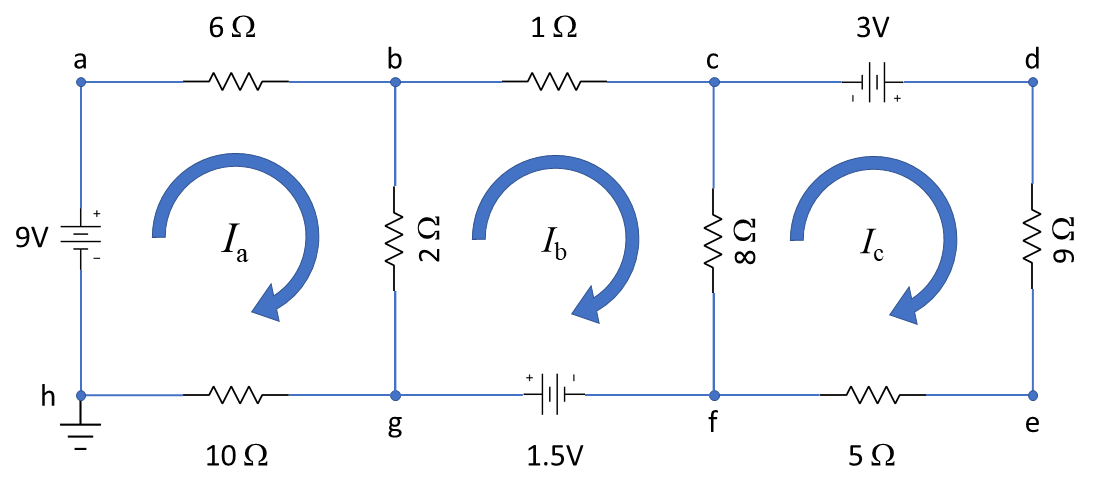

Resolver el conjunto de ecuaciones lineales para la corriente para $I_a$, $I_b$ e $I_c$ (en amperios)

% Voltajes
V = [9;1.5;3];


% coeficientes de la ecuación
R = [18 -2 0;
    -2 11 -8;
    0 -8 22];

% Resolver la corriente
I = R\V

I =     0.5507
    0.4564
    0.3023


Calcular la caída de voltaje a través de la resistencia de 8 ohmios entre los nodos c y f utilizando la Ley de Ohm y las corrientes $I_a$, $I_b$ e $I_c$ resueltas anteriormente.

Vcf = 8*(I(2)-I(3))

Vcf = 1.2323

These approaches also yield the correct value for Vcf

V = [1.5;9;3]; % Ib, Ia, Ic
R = [11 -2 -8;
    -2 18 0;
    -8 0 22];
I = R\V;
Vcf = 8*(I(1)-I(3))

Vcf = 1.2323

V = [3;-1.5;9]; % Ic, -Ib, Ia
R = [ 22 -8 0
    8 -11 2;
     0 -2 18];
I = R\V

I =     0.3023
    0.4564
    0.5507


Vcf = 8*(I(2)-I(1))

Vcf = 1.2323